**Download Dataset**

This data has been pre-processed from [Steinmetz et al. (2019)](https://www.nature.com/articles/s41586-019-1787-x), and is hosted on Sciebo here: [https://uni-bonn.sciebo.de/s/wjsBtZzUVjKaB3J](https://uni-bonn.sciebo.de/s/wjsBtZzUVjKaB3J).

# Analyzing Behavioral Task Performance: Psychometric Analysis on Ordered Categorical Data

In the experiment reported on by [Steinmetz et al, 2019 in Nature](https://www.nature.com/articles/s41586-019-1787-x), mice were tasked with turning a wheel to the left or right based on the relative contrast levels of two simultaneously-presented gradient  stimuli:

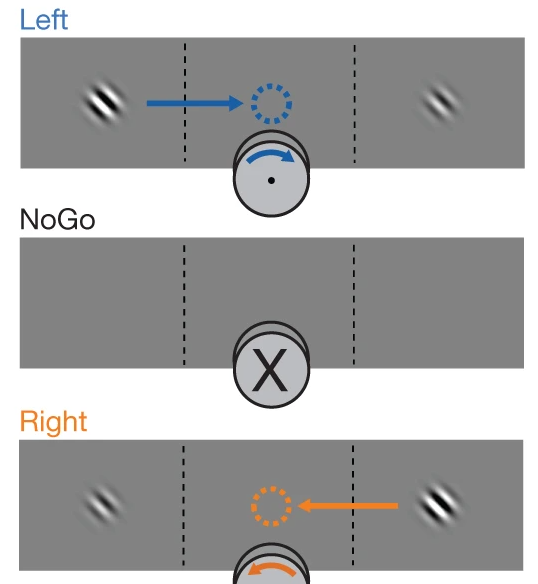

When the left stimuli is brightest, in order to earn a reward, the mouse must turn the wheel to the right. Accordingly when the right stimili is brightest, the mouse must turn the wheel to the right. When both stimili have equal contrasts (including the case where no stimili are shown), the correct response is not to turn the wheel. 

**Analysis Goals**

In this notebook, we'll examine the `response_time` and `response_type` of each trial across all sessions, to determine whether the mice  successfully performed the task, and whether the difference in contrast  levels between the two stimuli affected their performance.

## **Performance Analysis:  Average Response Type for Each Stimulus Contrast Level**

Read in data from .csv file. 

data = readtable("data/all.csv");
data

data = 14420×14 table
    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_type     mouse      session_date    session_id
    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    ________    ____________    __________

      1        {'true'}            100                0            

**Example Exercise**

Make a bar plot showing the mean response type according to contrast right levels

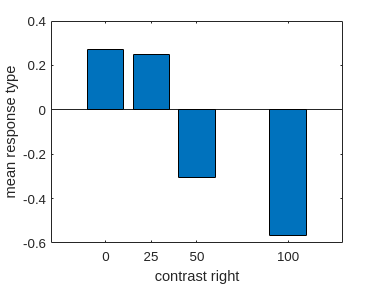

mean_response_type = groupsummary(data, "contrast_right", "mean", "response_type");

bar(mean_response_type.contrast_right, mean_response_type.mean_response_type)

xlabel("contrast right")
ylabel("mean response type")

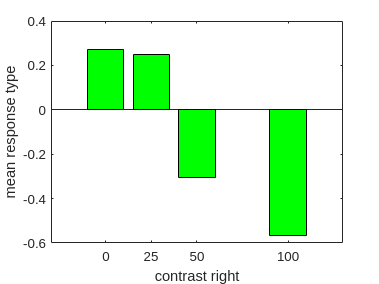

mean_response_type = groupsummary(data, "contrast_right", "mean", "response_type");

bar(mean_response_type.contrast_right, mean_response_type.mean_response_type, "green")

xlabel("contrast right")
ylabel("mean response type")

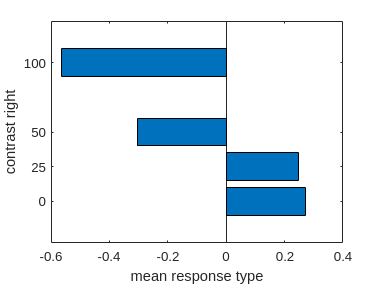

mean_response_type = groupsummary(data, "contrast_right", "mean", "response_type");

barh(mean_response_type.contrast_right, mean_response_type.mean_response_type)

ylabel("contrast right")
xlabel("mean response type")

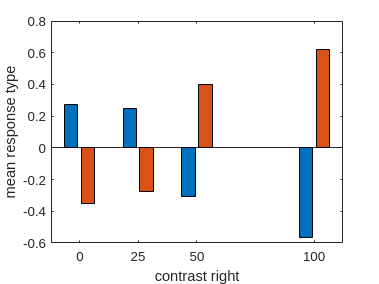

mean_response_type = groupsummary(data, "contrast_right", "mean", "response_type");
mean_response_type_l = groupsummary(data, "contrast_left", "mean", "response_type");

bar(mean_response_type.contrast_right, horzcat(mean_response_type.mean_response_type, mean_response_type_l.mean_response_type))
%bar(mean_response_type_l.contrast_left, mean_response_type_l.mean_response_type)

xlabel("contrast right")
ylabel("mean response type")

ans =     0.2723
    0.2476
   -0.3048
   -0.5655
    0.2723
    0.2476
   -0.3048
   -0.5655


ans =     0.2723    0.2723
    0.2476    0.2476
   -0.3048   -0.3048
   -0.5655   -0.5655
